close all

folder_name = strcat('b01_data_',int2str(idx));

p = 'orig';
file = strcat('data\', folder_name, '\',p,'Pc.csv')

file = 'data\b01_data_18255\origPc.csv'

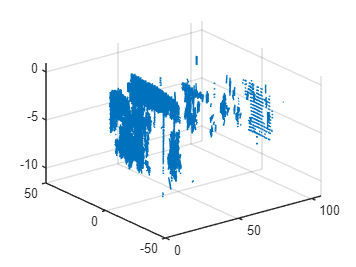

table = readtable(file);

table = sortrows(table,1);

x = table.Var1;
y = table.Var2;
z = table.Var3;
u = table.Var4;
v = table.Var5;
w = table.Var6;

quiver3(x,y,z,u,v,w)

X = [x,y]

X =     4.0167    0.4686
    4.0998    1.1098
    4.1095    0.8007
    4.1496    1.1157
    4.1512    0.6325
    4.1527    0.7586
    4.1716    0.7685
    4.1770    0.7756
    4.1813    0.7574
    4.1823    0.8148


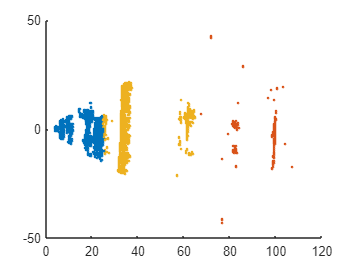


numGroups = 3;

j = kmeans(X,numGroups);
cmap = jet(numGroups); 
clf; hold on

for i=1:numGroups
    k = find(j==i);
    scatter3(x(k), y(k), z(k), '.', 'MarkerFaceColor',cmap(i,:)); 
end
hold off